# Filtro de Savitzky-Golay

Los coeficientes de este filtro resultan de una aporximacion polinomial que busca un siavizado de la señal. En esencia es un filtro FIR que no depende del concepto de enventanado.

Ejemplo:

n=0:511;% vector de tiempo
k=n/512;% vector de frecuencias
xn=sin(2*pi*n*1/4)+sin(2*pi*n*1/8)+sin(2*pi*n*1/32)+sin(2*pi*n*1/128);
xk=abs(fft(xn));

Se grafican la señal y su respectivo espectro de frecuencia

Identifique cada frecuencia y su ubicación en el dominio de la frecuencia

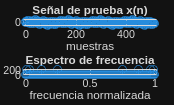

figure()
subplot(2,1,1);
stem(n,xn);
xlabel('muestras')
title('Señal de prueba x(n)');
subplot(2,1,2);
stem(k,xk);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Obtencion de los coeficentes del filtro

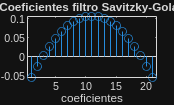

m = 3; % orden del polinomio
fl = 21; % longitud de la ventana del filtro
w = ones(fl,1); % hamming(fl); hann(fl);
b = sgolay(m,fl,w);
hn = b((fl+1)/2,:);

figure();
stem(hn);
xlabel('coeficientes');
title('Coeficientes filtro Savitzky-Golay');

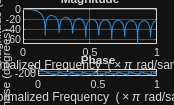


figure();
freqz(hn,1);

Aplicando el filtro

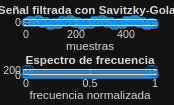

yn=filter(hn,1,xn);
yk=abs(fft(yn));

figure()
subplot(2,1,1)
stem(n,yn);
xlabel('muestras')
title('Señal filtrada con Savitzky-Golay');
subplot(2,1,2);
stem(k,yk);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');